# SAMEKO - Reimbursement rules ERS

WP with Kristofer & Arne

## Input

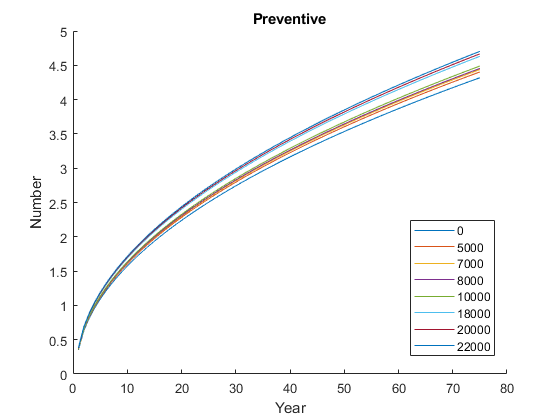

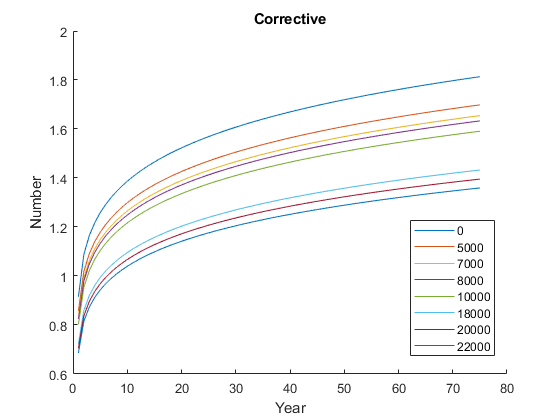

clear global
clear all
clc

% read regression results
[~,~,~,renewal,MGT,nb_freight_year,nb_pass_year,delay_min,MGT_lifetime,~, ERS] = read_input_data();
switches = 1;% 2 3 4 5 6 7];
year_lifetime = ceil(MGT_lifetime(switches)./8);
ERS_levels = 1:8;
headers = {0	5000	7000	8000	10000	18000	20000	22000}';
renewal_costs_switches = renewal(switches);
% reconvert to different ERS levels
MGT = MGT(switches)*ones(size(headers));
nb_freight_year = nb_freight_year(switches)*ones(size(headers));
nb_pass_year = nb_pass_year(switches)*ones(size(headers));
delay_min = delay_min(switches)*ones(size(headers));
MGT_lifetime = MGT_lifetime(switches)*ones(size(headers));
year_lifetime = year_lifetime(switches)*ones(size(headers));
renewal_costs_switches = renewal_costs_switches(switches)*ones(size(headers));
% set parameters
time_horizon_switches_max = 75;
prev_ERS = ERS{1};
korr_ERS = ERS{2};
fail_ERS = ERS{3};
% plot all inputs
data = {prev_ERS, korr_ERS, fail_ERS, headers};
plot_figure("input", data);

## LCC 

% LCC for the time_horizon_switches
[dir_maint,prev_cap,korr_cap,disr] = assess_lcc(prev_ERS,korr_ERS,fail_ERS,MGT,nb_freight_year,nb_pass_year,delay_min,time_horizon_switches_max,{ERS_levels headers},1);
% plot the yearly undiscounted costs
data = {dir_maint, prev_cap, korr_cap, disr, renewal_costs_switches, headers};
% plot_figure("yearly undiscounted",data);
% annuity
[ann,tpv] = get_ann_tpv(dir_maint, prev_cap, korr_cap, disr, renewal_costs_switches, year_lifetime)

ann = 	1.0e+05 *

    3.4223    3.3620    3.3408    3.3322    3.3399    3.3903    3.3876    3.3850


tpv = 	1.0e+06 *

    9.6032    9.4341    9.3746    9.3505    9.3720    9.5136    9.5059    9.4987


## Annuity and optimal lifetime

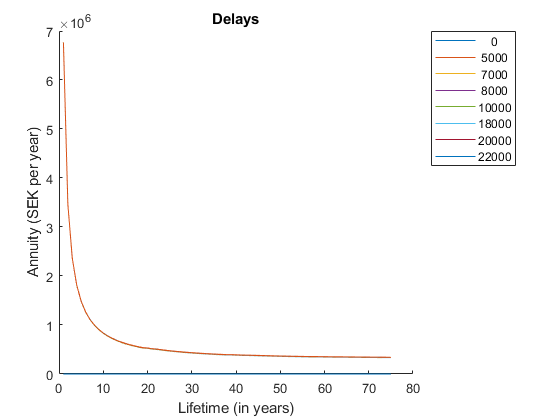

% Annuity for different lifetimes
nb_headers = size(headers,1);
annuity_switches = zeros(time_horizon_switches_max,nb_headers);
tpv = zeros(time_horizon_switches_max,nb_headers);
for y=1:time_horizon_switches_max
    [dir_maint,prev_cap,korr_cap,disr] = assess_lcc(prev_ERS,korr_ERS,fail_ERS,MGT,nb_freight_year,nb_pass_year,delay_min,y,{ERS_levels headers},1);
    [annuity_switches(y,:), tpv(y,:)] = get_ann_tpv(dir_maint, prev_cap, korr_cap, disr, renewal_costs_switches, year_lifetime);
end
% Annuity for switches
plot(1:time_horizon_switches_max, annuity_switches)
headers_char = char(num2str(cell2mat(headers)));
legend(headers_char, "Location","bestoutside")
xlabel("Lifetime (in years)")
ylabel("Annuity (SEK per year)")

% Find the optimal lifetime (where annuity is minimal)
[min_annuity_switches, optimal_lifetime_switches] = min(annuity_switches,[], 1)

min_annuity_switches = 	1.0e+05 *

    3.4223    3.3620    3.3408    3.3322    3.3399    3.3903    3.3876    3.3850


optimal_lifetime_switches =     75    75    75    75    75    75    75    75


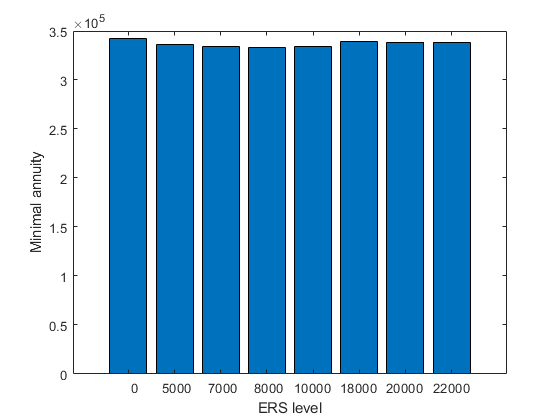

% minimal annuity
figure;
bar(min_annuity_switches);
xlabel('ERS level');
ylabel('Minimal annuity');
set(gca, 'XTick', 1:length(headers), 'XTickLabel', headers_char);